%This should be opened second. The network should already be loaded 
%into the workspace so you don't have to load again and wait for so long
%This gives you the treatment based on the image you upload
%load all the treatments
MT = imread("Mtreatment.png");
GT= imread("Gtreatment.png");
PT = imread("Ptreatment.png");
%
%load any image from the ApplicationGrader folder
%I chose a pituitary tumor. But there are 4 files total. One image per
%class. Change this based of off what you want to test. 

img = imread("pituitary.jpg");

img = 619×495×3 uint8 array
img(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

img = imresize(img, [227 227]);

img = 227×227×3 uint8 array
img(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

%write the label as either "no_tumor", "pituitary_tumor","glioma_tumor",or
%"meningioma_tumor" with no space before or after
tumlabel = input("What kind of tumor is this: ","s")

tumlabel = 'pituitary_tumor'

%give prediction classification of the given dataset
tumprediction = classify(net,img)

tumprediction = categorical
     pituitary_tumor 


Pituitary tumor diagnosed. The treatment is : 


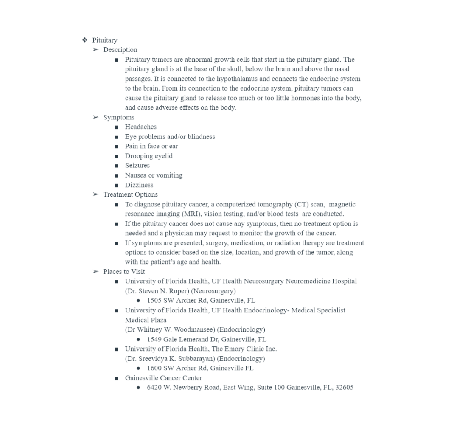

if tumlabel == tumprediction
   fprintf("Correct Classification")
if tumlabel == name(1,1)
    fprintf("Glioma tumor diagnosed. The treatment is : \n")
    imshow(GT)
elseif tumlabel == name(2,1)
 fprintf("M tumor diagnosed. The treatment is : \n")
 imshow(MT)
 elseif tumlabel == name(3,1)
 fprintf("No tumor diagnosed. No treatment required \n")
 
elseif tumlabel == name(4,1)
 fprintf("Pituitary tumor diagnosed. The treatment is : \n")
 imshow(PT)
end
else 
    fprintf("The image classifier did not work. Choose another image.")

end